# Langtidsdrift

clc; clear all;

LTD = importdata("LangTidsDrift.txt");
MD = importdata("MegetData.txt"); % slush
brine = importdata("BrineNedcool.txt");

CP = py.importlib.import_module("CoolProp.CoolProp");

MD_Tbrine = find(MD.textdata(1,2:end) == "Brinetemperatur")

MD_Tbrine = 4

LTD_Tbrine = find(LTD.textdata(1,2:end) == "Brinetemperatur")

LTD_Tbrine = 4

brine_Tbrine = find(brine.textdata(1,2:end) == "Brinetemperatur")

brine_Tbrine = 4

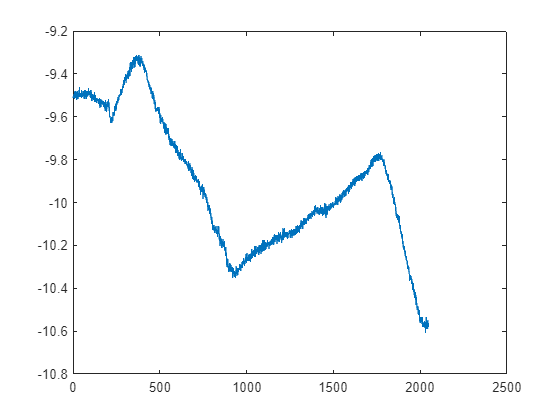


ind = 10;

MD_Tbrine = MD.data(ind:end-ind, MD_Tbrine);
LTD_Tbrine = LTD.data(ind:end-ind, LTD_Tbrine);
brine_Tbrine = brine.data(ind:end-ind, brine_Tbrine);

figure
plot(MD_Tbrine)

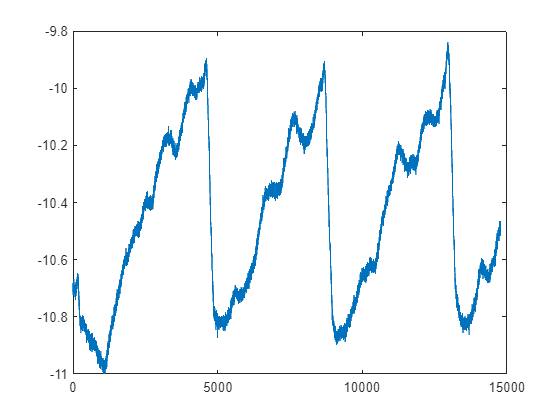


figure
plot(LTD_Tbrine)

# Nedkøling af brine

brine_Tefordamp = find(brine.textdata(1,2:end) == "Temperaturen efter fordamper");
brine_Tffordamp = find(brine.textdata(1,2:end) == "Temperatur efter EPV")

brine_Tffordamp = 9


brine_Tffordamp = brine.data(ind:end-ind, brine_Tffordamp);
brine_Tefordamp = brine.data(ind:end-ind, brine_Tefordamp);

ind_plot = find(max(brine_Tbrine) == brine_Tbrine)

ind_plot = 158

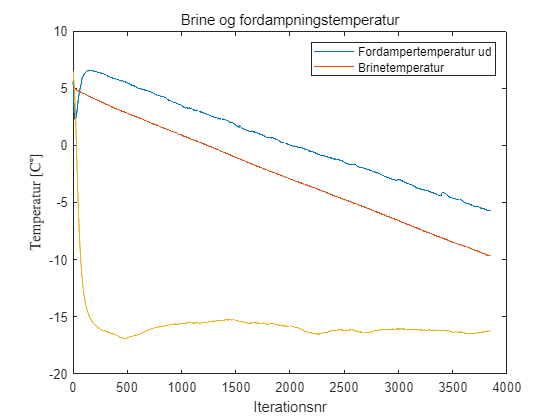




figure

plot(brine_Tefordamp(ind_plot:4000))
hold on
plot(brine_Tbrine(ind_plot:4000))
plot(brine_Tffordamp(ind_plot:4000))
hold off

title("Brine og fordampningstemperatur","FontWeight","normal")

legend("Fordampertemperatur ud","Brinetemperatur","location","northeast")

xlabel("Iterationsnr")
ylabel("Temperatur $[\mathrm{C}^\circ]$","Interpreter","latex")

# Kompressortemperatur

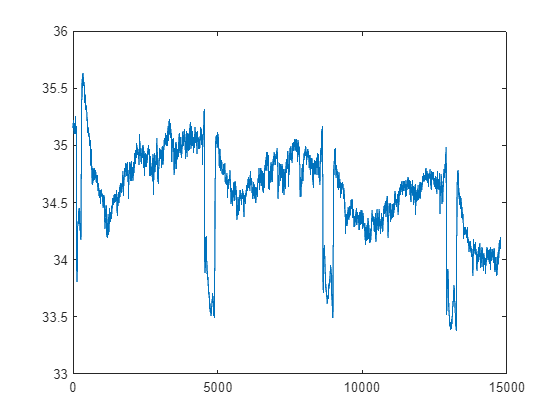

LTD_komptemp = find(LTD.textdata(1,2:end) == "Kompressortemperatur");

LTD_komptemp = LTD.data(ind:end-ind, LTD_komptemp);

figure
plot(LTD_komptemp)

T_komp = find(LTD.textdata(1,2:end) == "Temperaturen efter fordamper")

T_komp = 6

T_kond = find(LTD.textdata(1,2:end) == "Temperatur efter kompressor")

T_kond = 10

T_EPV = find(LTD.textdata(1,2:end) == "Temperatur efter kondensator ")

T_EPV = 11

T_fordamp = find(LTD.textdata(1,2:end) == "Temperatur efter EPV")

T_fordamp = 9

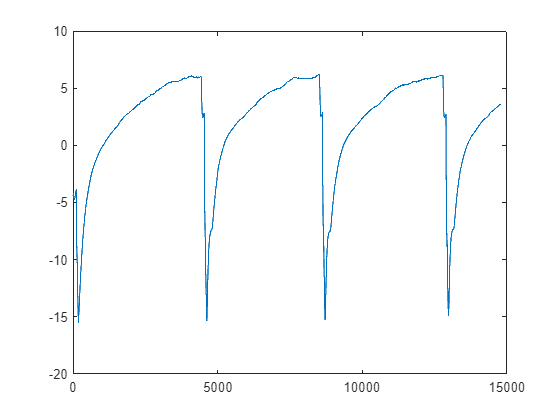



T_efordamp = LTD.data(ind:end-ind, T_komp);
T_ffordamp = LTD.data(ind:end-ind, T_fordamp);

figure
plot(T_efordamp)

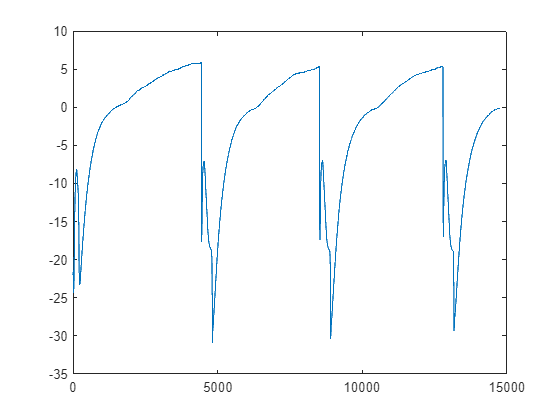


figure
plot(T_ffordamp)